tic

# **Labs 7&8**

***One document, 5 minute running time.***

# Lab 7

#### Event selection optimization 

High $p_T$ dataset

Data setup...

h5disp("higgs_100000_pt_1000_1200.h5")

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

## 1. Stacked Histogram Plot for Mass

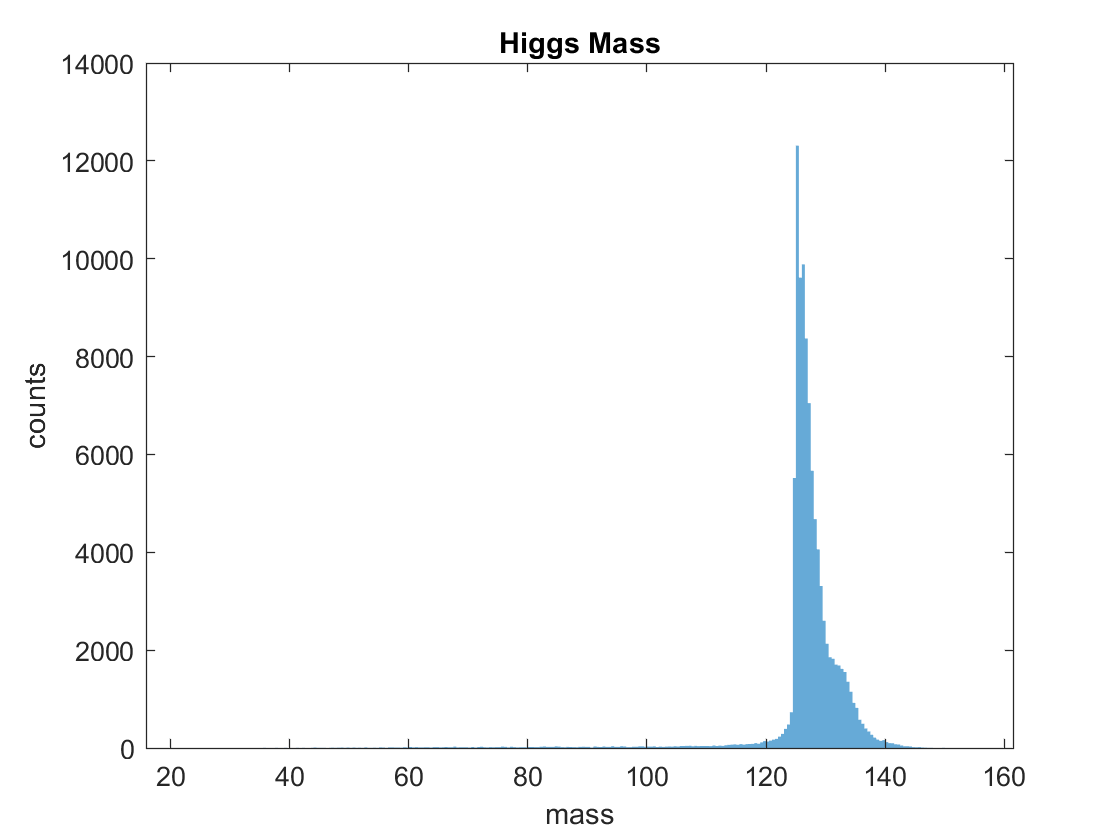

histogram(higgs(4,:),'EdgeColor','none');
title('Higgs Mass')
xlabel('mass')
ylabel('counts')

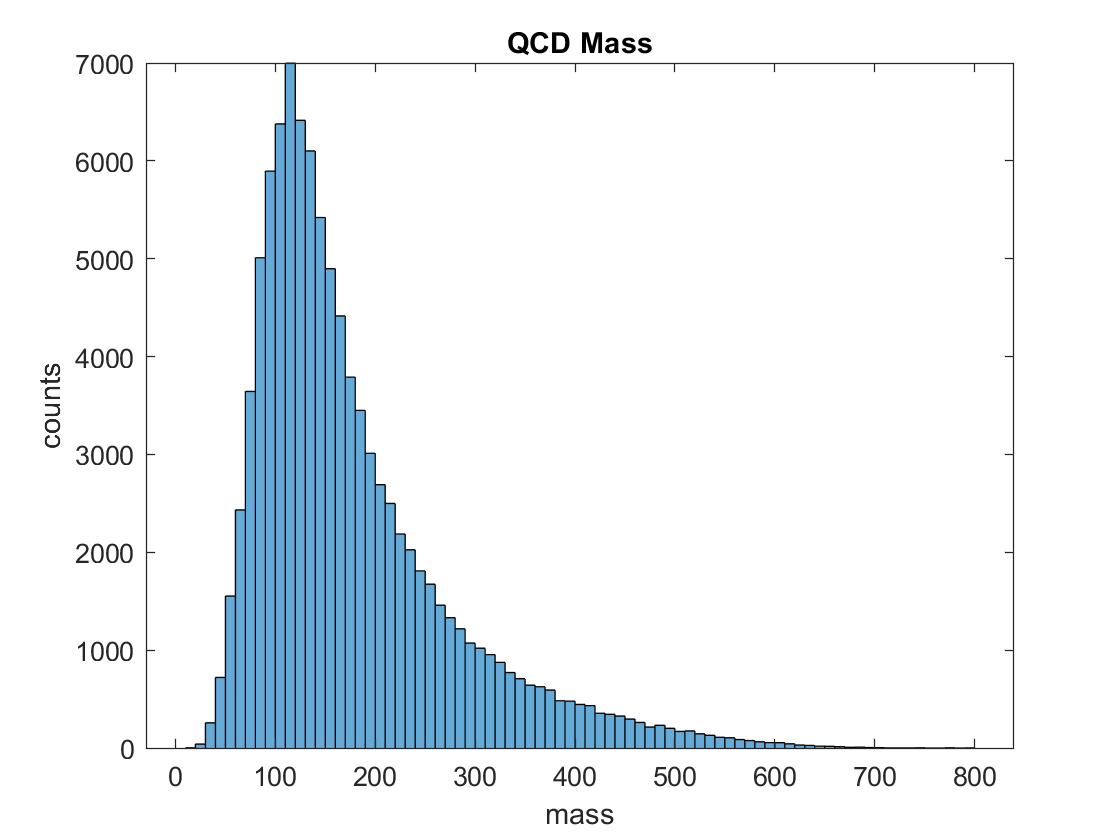

histogram(qcd(4,:),'EdgeColor','none');
title('QCD Mass')
xlabel('mass')
ylabel('counts')

Nhiggs = 50;
Nqcd = 2000;

### Evaluating base expected significance with Poisson statistics:

poiss = makedist('Poisson','lambda',2000);
signal = 2050;

pr = cdf(poiss,signal)

pr = 0.8704

sigma = norminv(pr)

sigma = 1.1282

### Comparison to the event number ratio:

ratio = Nhiggs/(sqrt(Nqcd))

ratio = 1.1180

The value of the ratio is very close to the calculated sigma value, with a difference of about 0.01. Therefore, I can use the ratio to calculate significance in my data. 

Number of events is a Poisson distribution with $\lambda$ equal to $N_{\textrm{Higgs}} \;$or $N_{\textrm{qcd}}$ so the ratio represents standard deviation. 

## 2. Identifying Mass Cuts to Optimize Significance

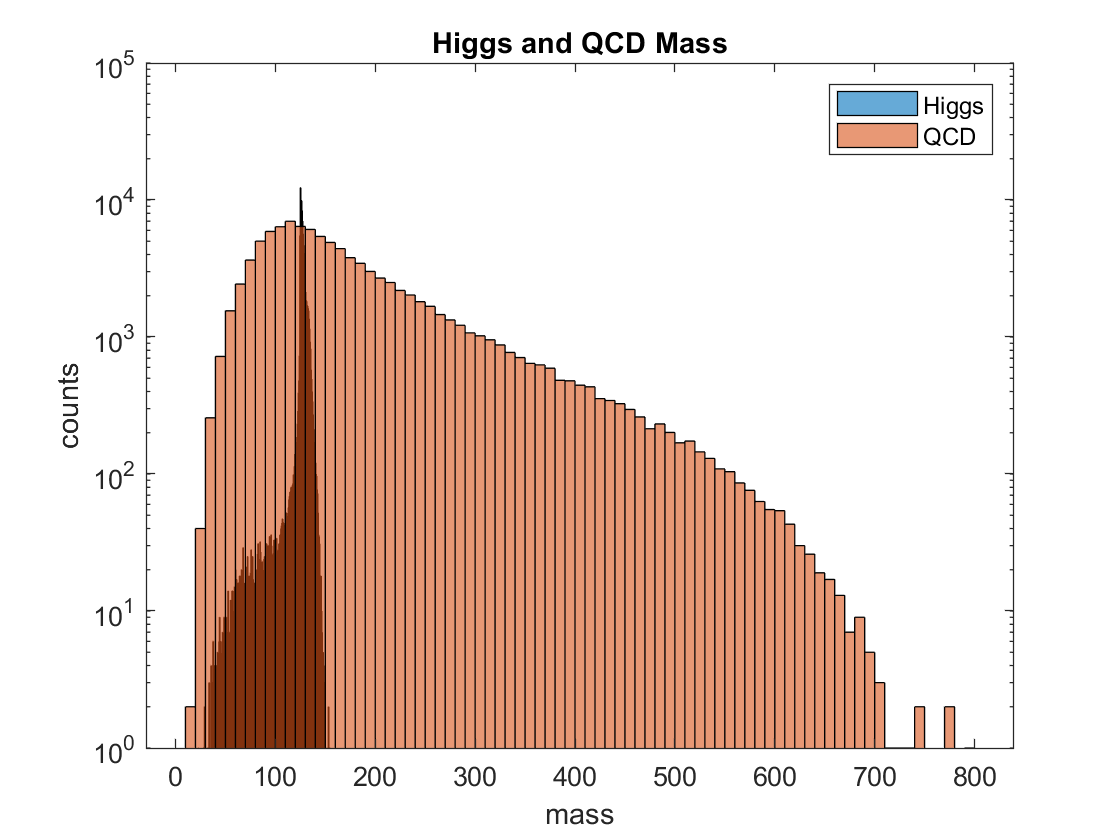

histogram(higgs(4,:),'EdgeColor','none');
hold on
histogram(qcd(4,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD Mass')
xlabel('mass')
ylabel('counts')
legend('Higgs','QCD')
hold off

### Initial cut:

The majority of the Higgs data runs from about 100 to 140, so I'll use those values for my initial cut limits. I'm using a for loop to cut my data and assigning a value of 1 to the data within [100,140] and a value of 0 to the data outside of it, with all values saved two vectors (one for each dataset). Using the 0s and 1s, the sum of each vector will give me the number of datapoints within my range, and I can use that value to scale down $N_{\textrm{Higgs}}$ and $N_{\textrm{qcd}}$ appropriately. I will then calculate my expected significance with the ratio $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{qcd}} }}$.  

l = length(higgs(4,:));
hcount = zeros(1,l);

for i = 1:l
    if (100 < higgs(4,i)) && (higgs(4,i) < 140)
        hcount(i) = 1;
    else
        hcount(i) = 0;
    end
end

Nhiggs = sum(hcount)*50/l

Nhiggs = 48.6715


bcount = zeros(1,l);

for i = 1:l
    if (100 < qcd(4,i)) && (qcd(4,i) < 140)
        bcount(i) = 1;
    else
        bcount(i) = 0;
    end
end

Nqcd = sum(bcount)*2000/l

Nqcd = 517.8000

significance = Nhiggs/(sqrt(Nqcd))

significance = 2.1389

With my initial cut, the significance already increases a full sigma.

### Systematic cuts:

My systematic cuts use the same method as above, with additional for loops to run through all potential value ranges. 

hmax = 125;
step = 0.5;
j = 100:step:hmax;
k = hmax+step:step:140;
J = length(j);
K = length(k);


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(4,i)) && (higgs(4,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(4,p)) && (qcd(4,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M = zeros(1,14);

[A,B] = max(sigs,[],"all",'linear');
M(4) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 4.4627

coordinates = zeros(16,2);
coordinates(4,1) = j(b);
coordinates(4,2) = k(a);

So the interval resulting in the maximum significance, $4\ldotp 46\sigma$, is $120\le \textrm{mass}\le 130$. 

Here's the representative histogram:

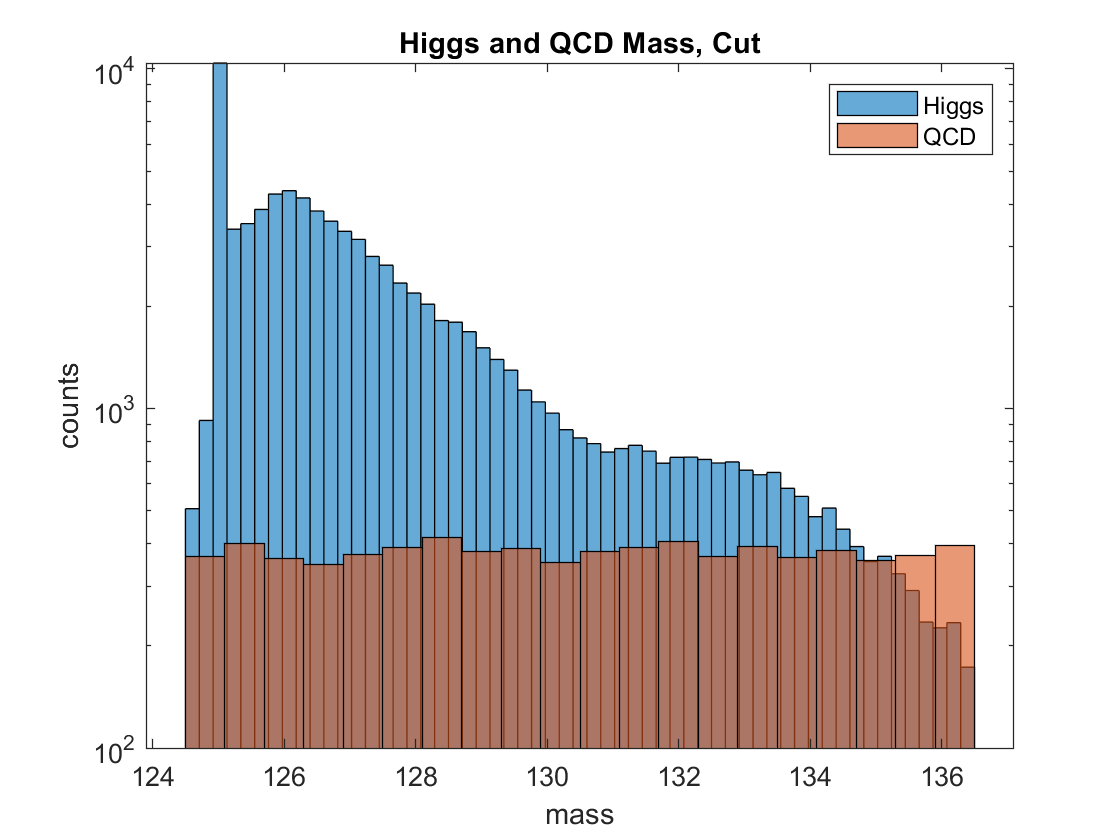

histogram(higgs(4,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(4,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD Mass, Cut')
xlabel('mass')
ylabel('counts')
legend('Higgs','QCD')
hold off

## 3. Histograms for the Rest of the Features

### No event selection:

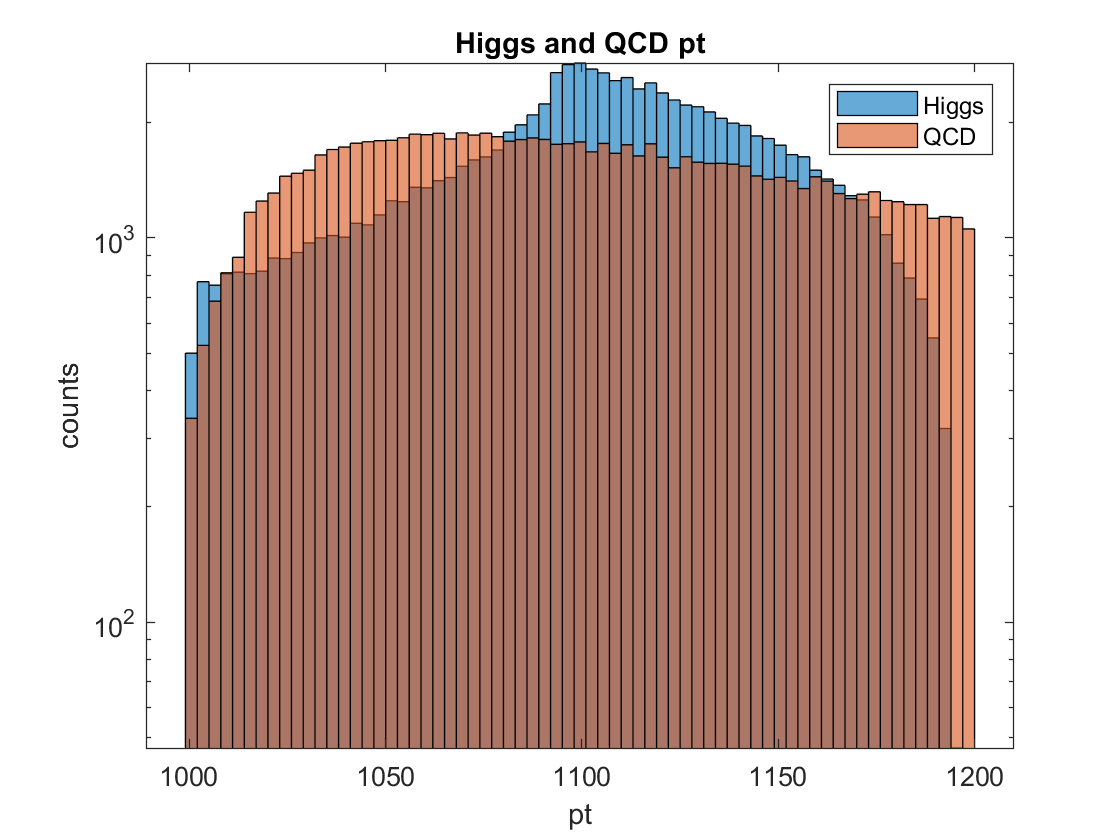

%pt
histogram(higgs(1,:),'EdgeColor','none');
hold on
histogram(qcd(1,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD pt')
xlabel('pt')
ylabel('counts')
legend('Higgs','QCD')
hold off

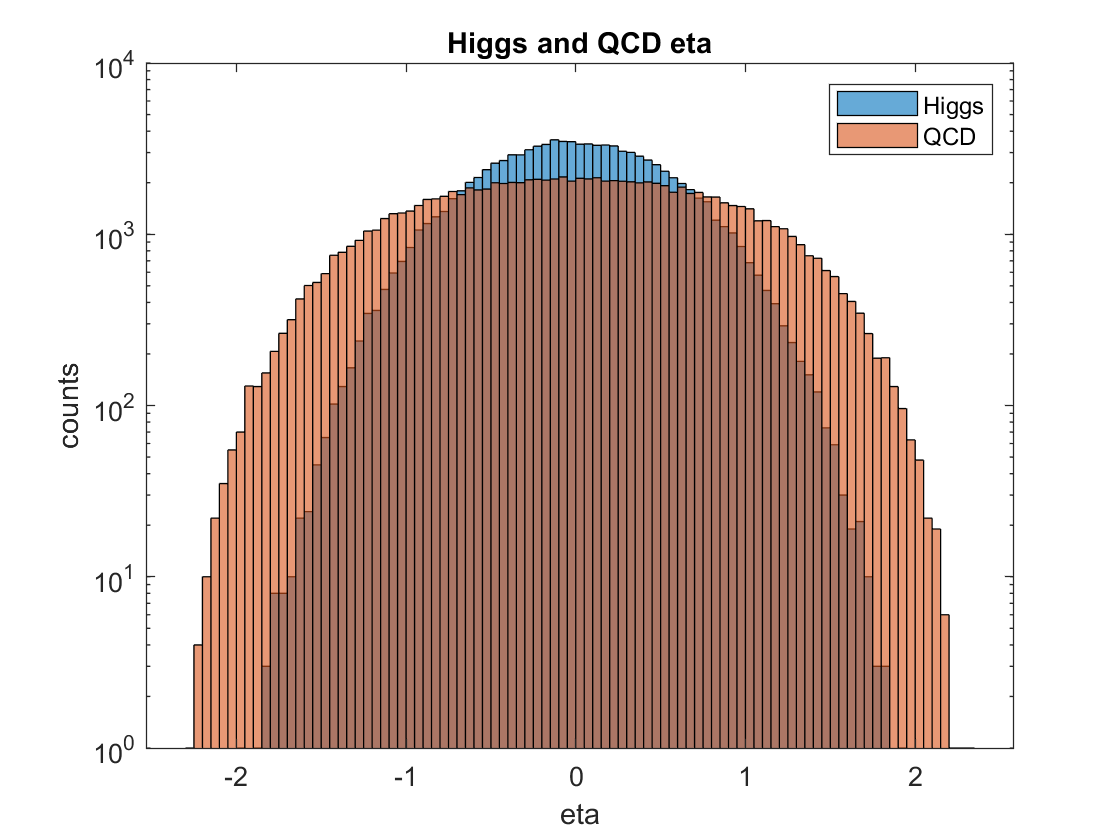

%eta
histogram(higgs(2,:),'EdgeColor','none');
hold on
histogram(qcd(2,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD eta')
xlabel('eta')
ylabel('counts')
legend('Higgs','QCD')
hold off

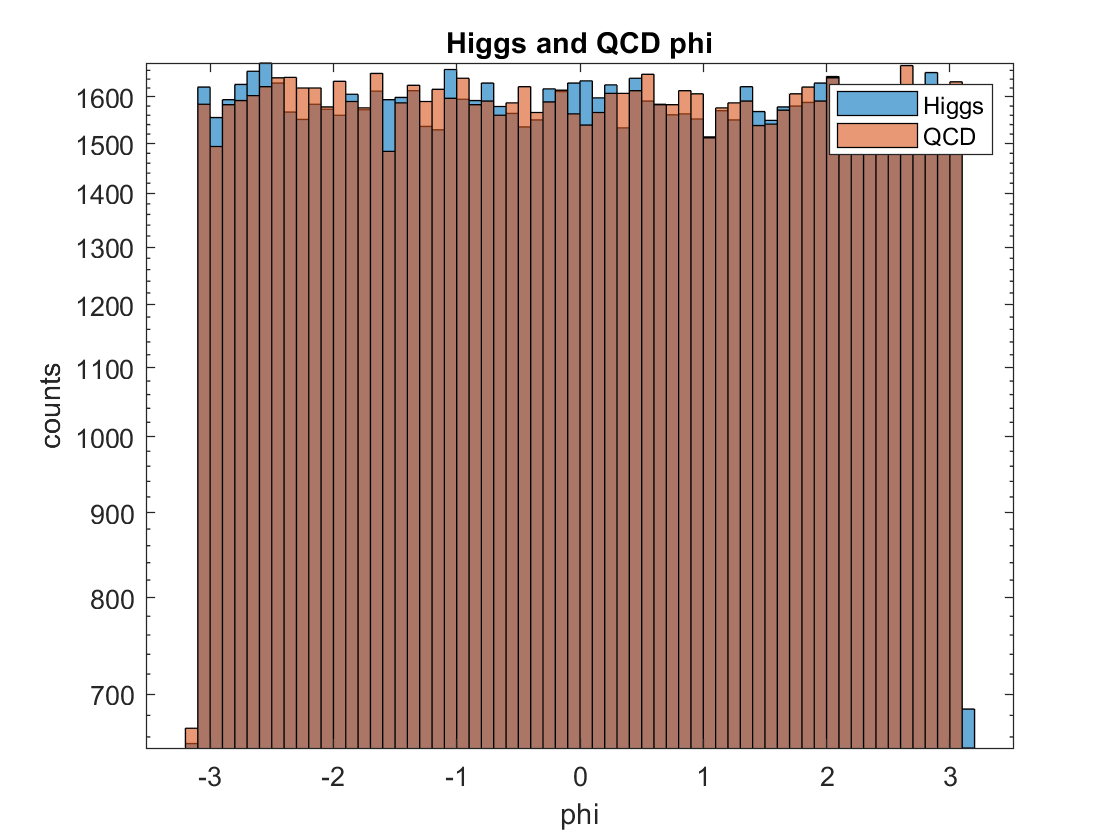

%phi
histogram(higgs(3,:),'EdgeColor','none');
hold on
histogram(qcd(3,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD phi')
xlabel('phi')
ylabel('counts')
legend('Higgs','QCD')
hold off

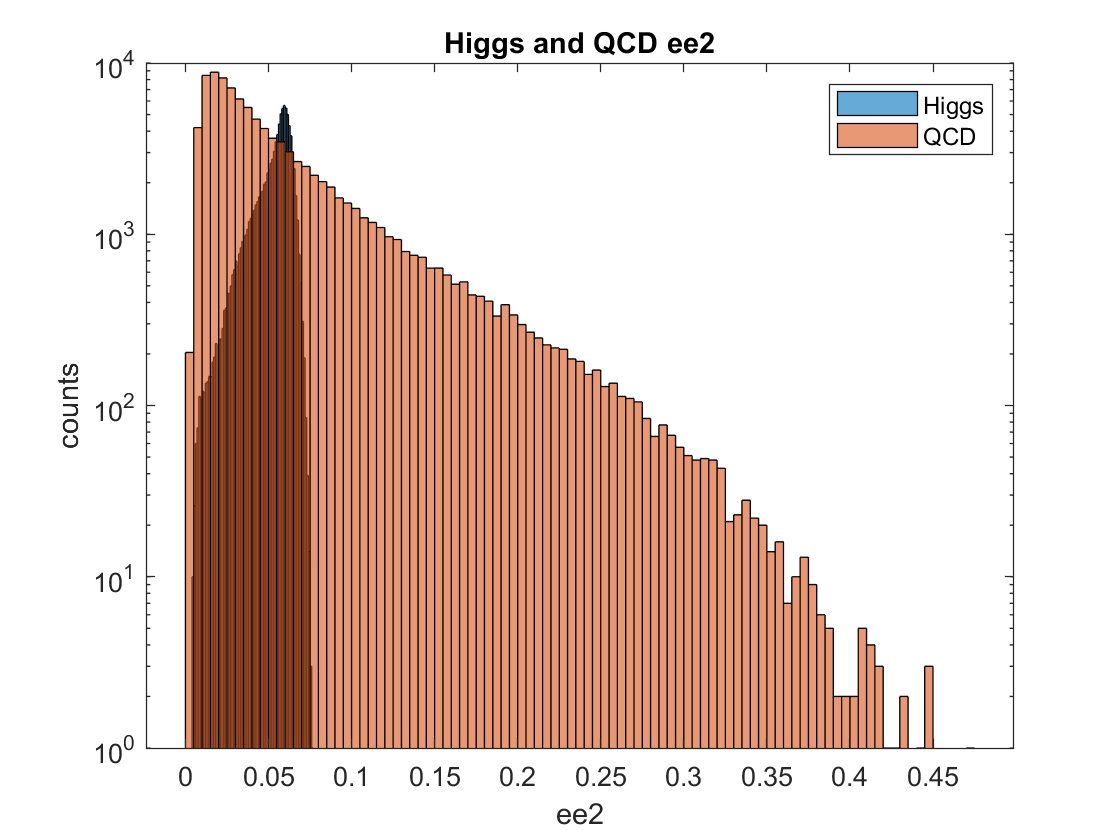

%ee2
histogram(higgs(5,:),'EdgeColor','none');
hold on
histogram(qcd(5,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD ee2')
xlabel('ee2')
ylabel('counts')
legend('Higgs','QCD')
hold off

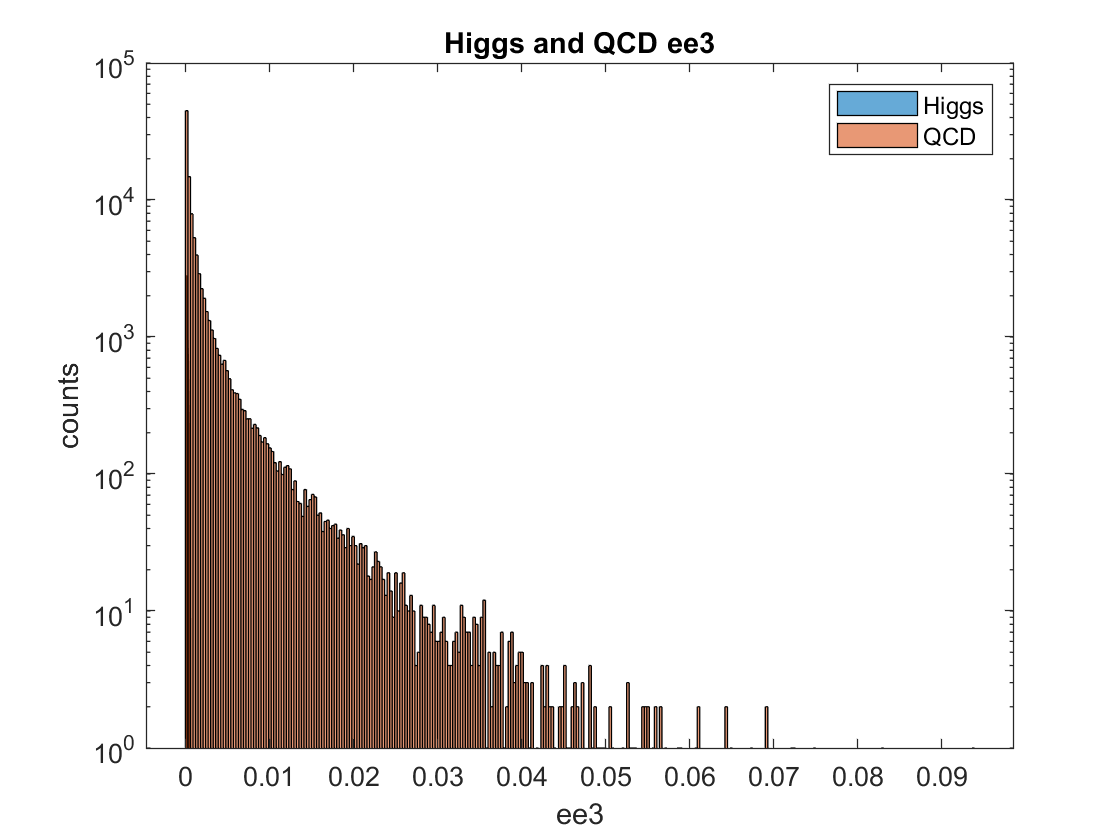

%ee3
histogram(higgs(6,:),'EdgeColor','none');
hold on
histogram(qcd(6,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD ee3')
xlabel('ee3')
ylabel('counts')
legend('Higgs','QCD')
hold off

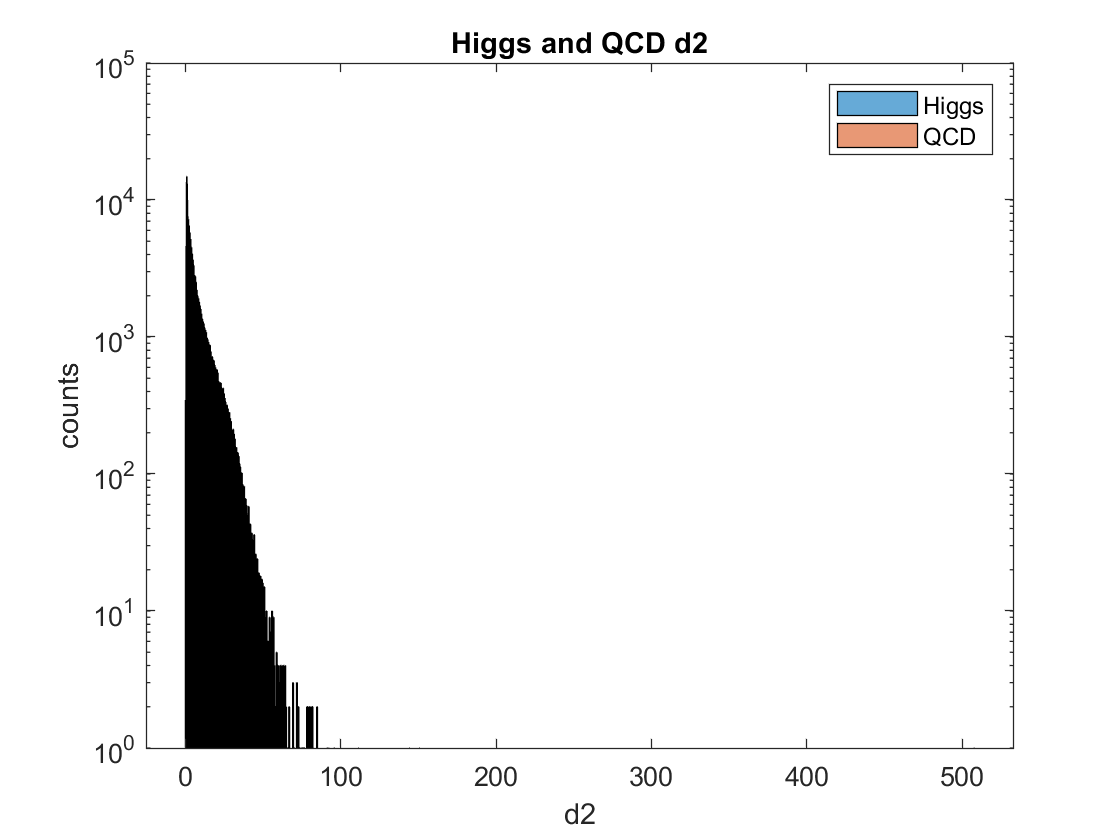

%d2
histogram(higgs(7,:),'EdgeColor','none');
hold on
histogram(qcd(7,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD d2')
xlabel('d2')
ylabel('counts')
legend('Higgs','QCD')
hold off

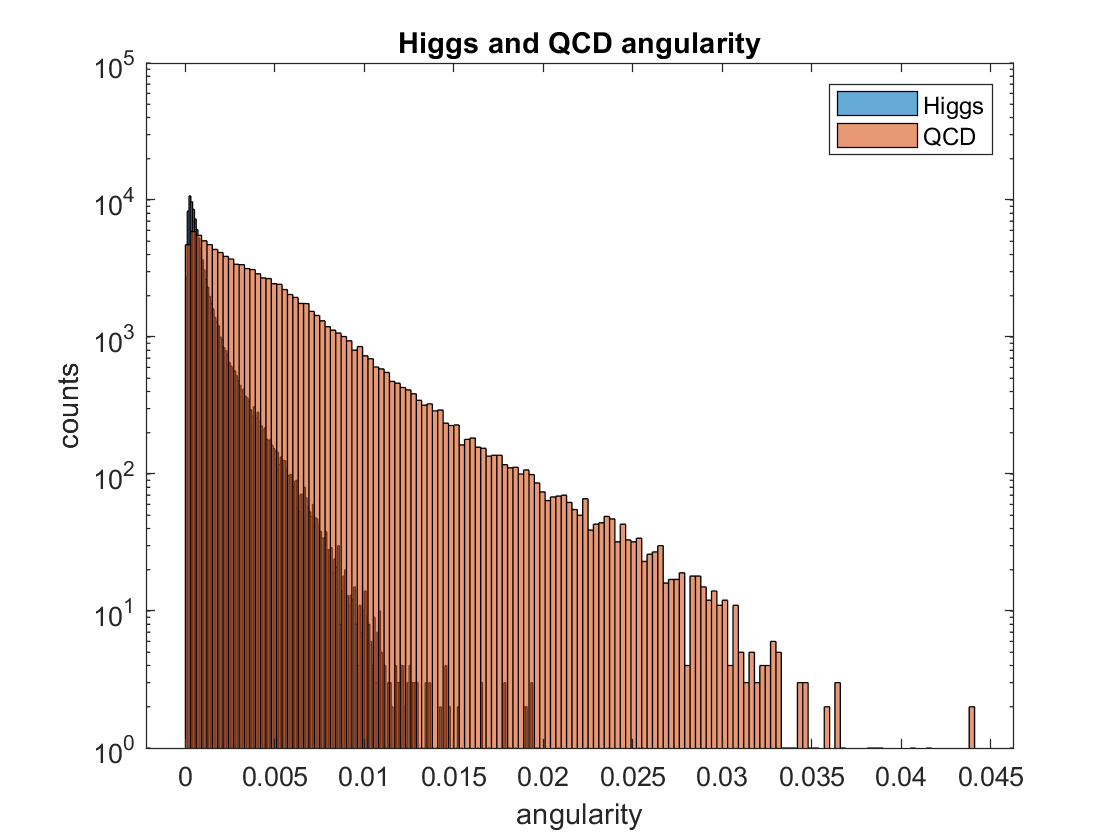

%angularity
histogram(higgs(8,:),'EdgeColor','none');
hold on
histogram(qcd(8,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD angularity')
xlabel('angularity')
ylabel('counts')
legend('Higgs','QCD')
hold off

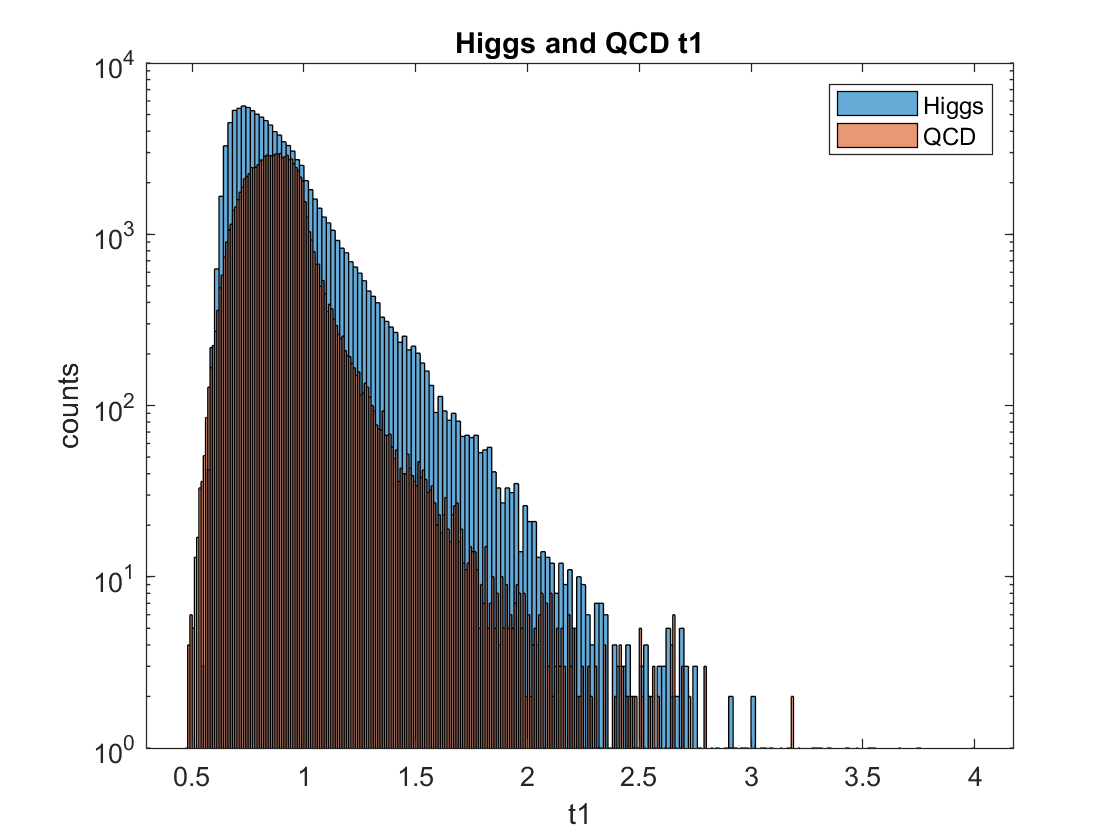

%t1
histogram(higgs(9,:),'EdgeColor','none');
hold on
histogram(qcd(9,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t1')
xlabel('t1')
ylabel('counts')
legend('Higgs','QCD')
hold off

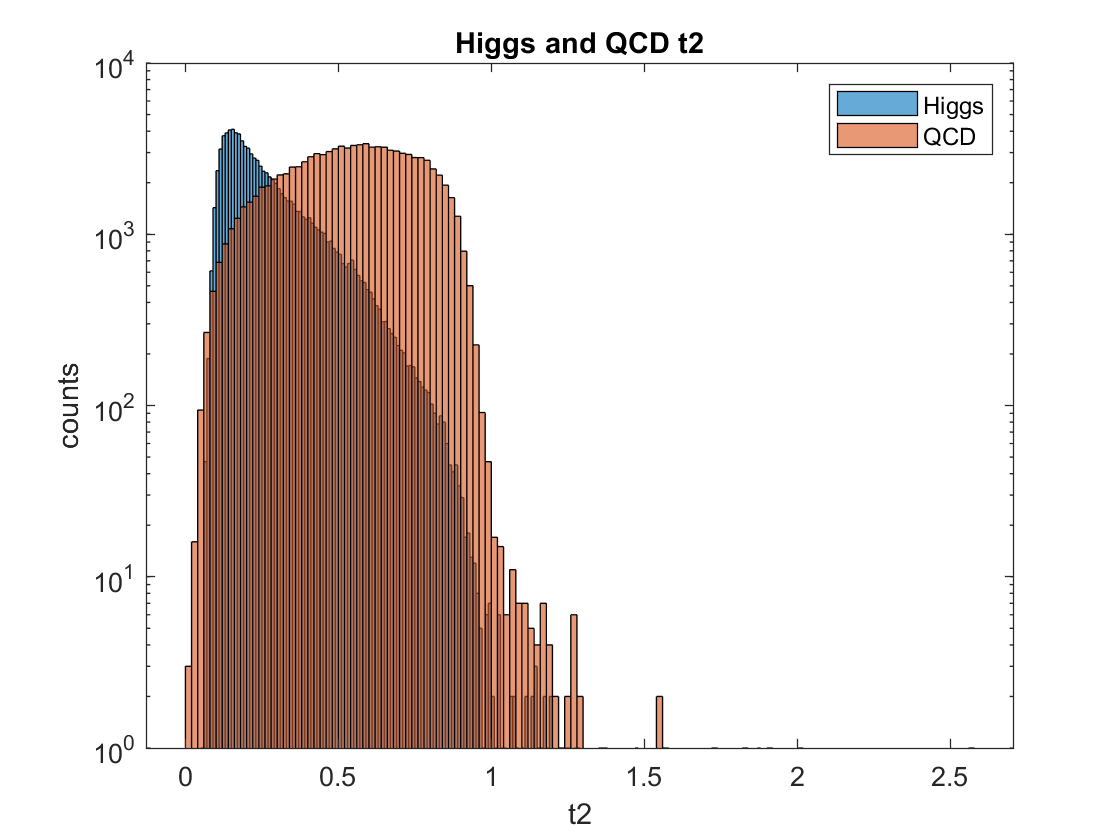

%t2
histogram(higgs(10,:),'EdgeColor','none');
hold on
histogram(qcd(10,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t2')
xlabel('t2')
ylabel('counts')
legend('Higgs','QCD')
hold off

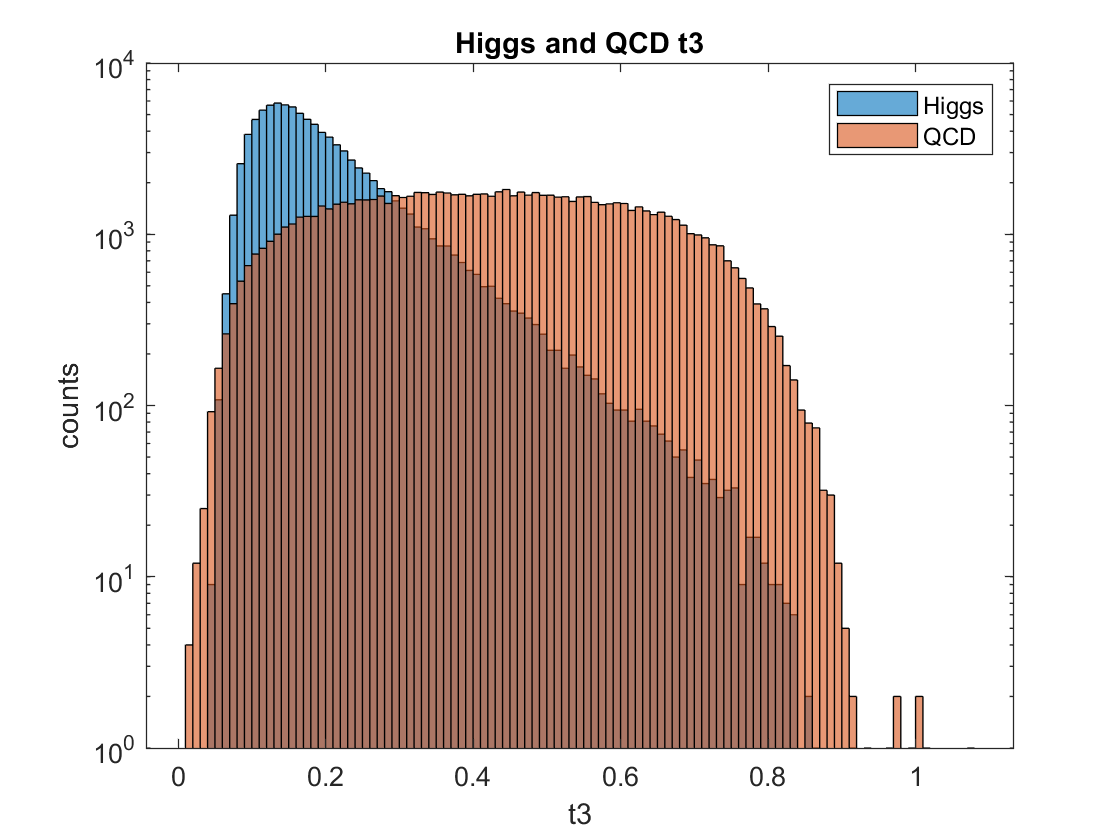

%t3
histogram(higgs(11,:),'EdgeColor','none');
hold on
histogram(qcd(11,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t3')
xlabel('t3')
ylabel('counts')
legend('Higgs','QCD')
hold off

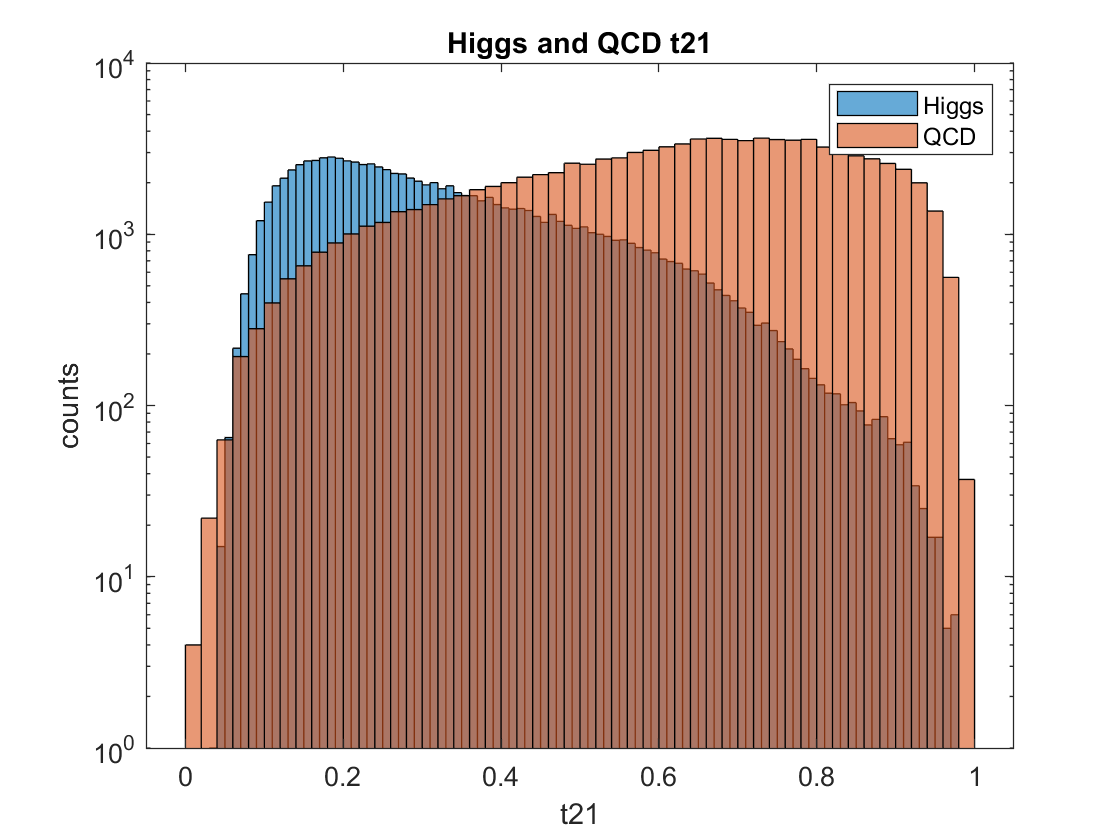

%t21
histogram(higgs(12,:),'EdgeColor','none');
hold on
histogram(qcd(12,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t21')
xlabel('t21')
ylabel('counts')
legend('Higgs','QCD')
hold off

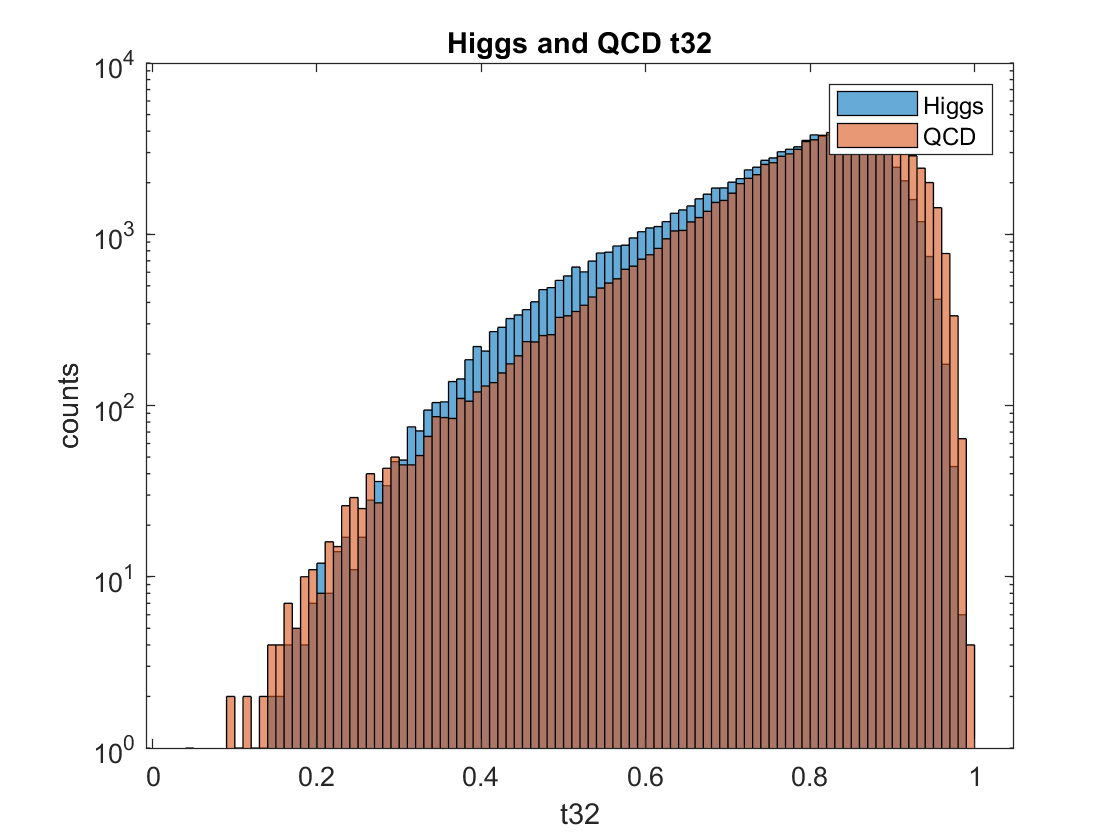

%t32
histogram(higgs(13,:),'EdgeColor','none');
hold on
histogram(qcd(13,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t32')
xlabel('t32')
ylabel('counts')
legend('Higgs','QCD')
hold off

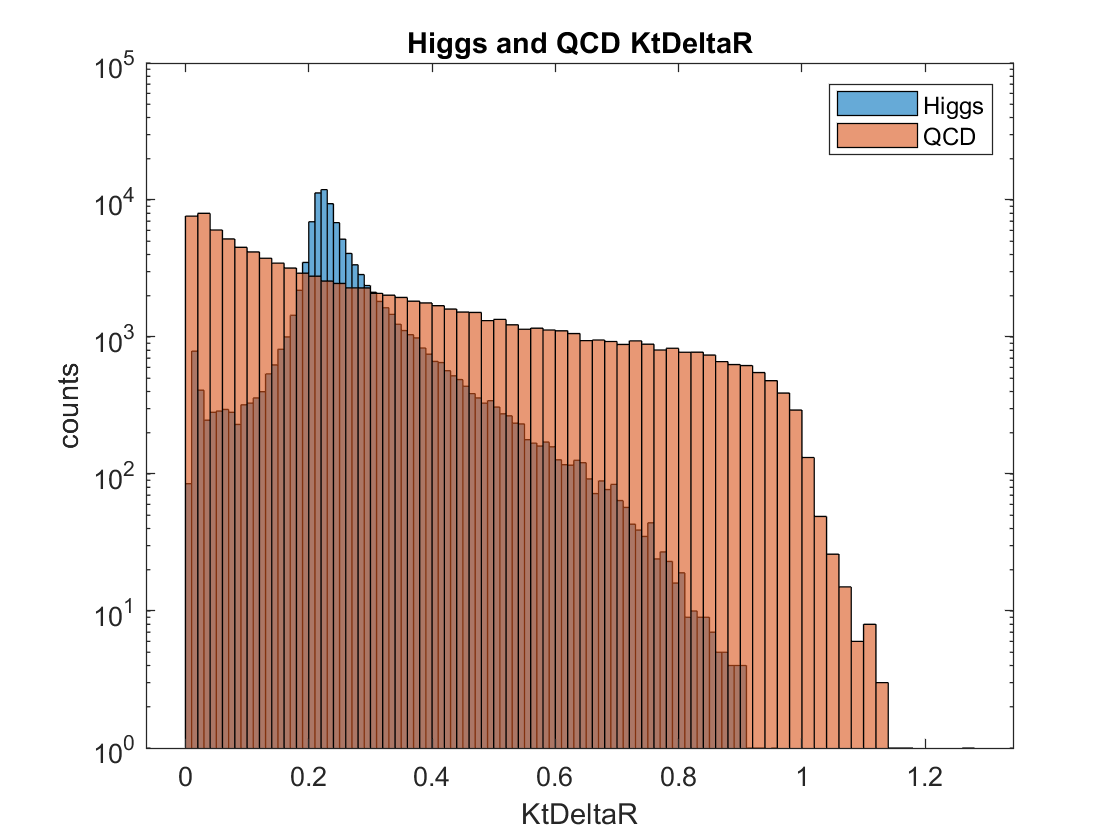

%KtDeltaR
histogram(higgs(14,:),'EdgeColor','none');
hold on
histogram(qcd(14,:),'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD KtDeltaR')
xlabel('KtDeltaR')
ylabel('counts')
legend('Higgs','QCD')
hold off

### Significance calculations and optimized histograms:

%pt
hmax = 1040;
step = 5;
j = 1000:step:hmax;
k = hmax+step:step:1200;
J = length(j);
K = length(k);
r = 1;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.1334

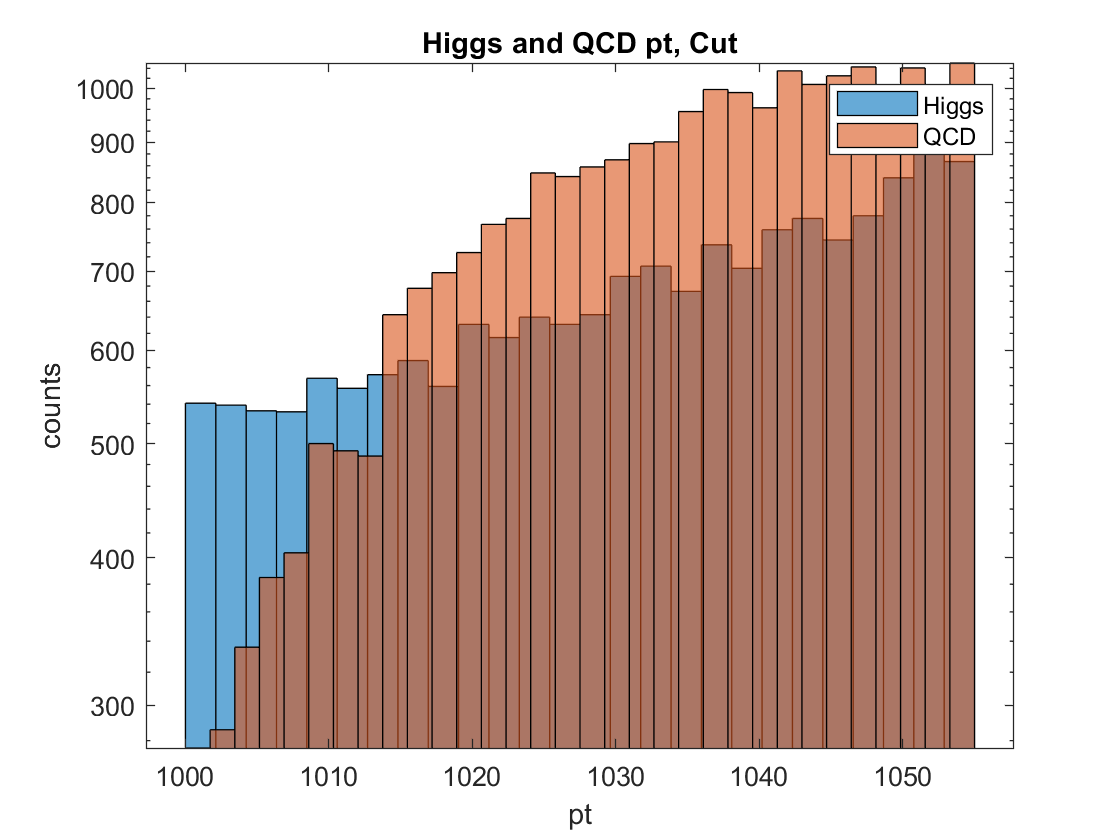

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD pt, Cut')
xlabel('pt')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%eta
hmax = 0;
step = 0.1;
j = -2:step:hmax;
k = hmax+step:step:2;
J = length(j);
K = length(k);
r = 2;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.2092

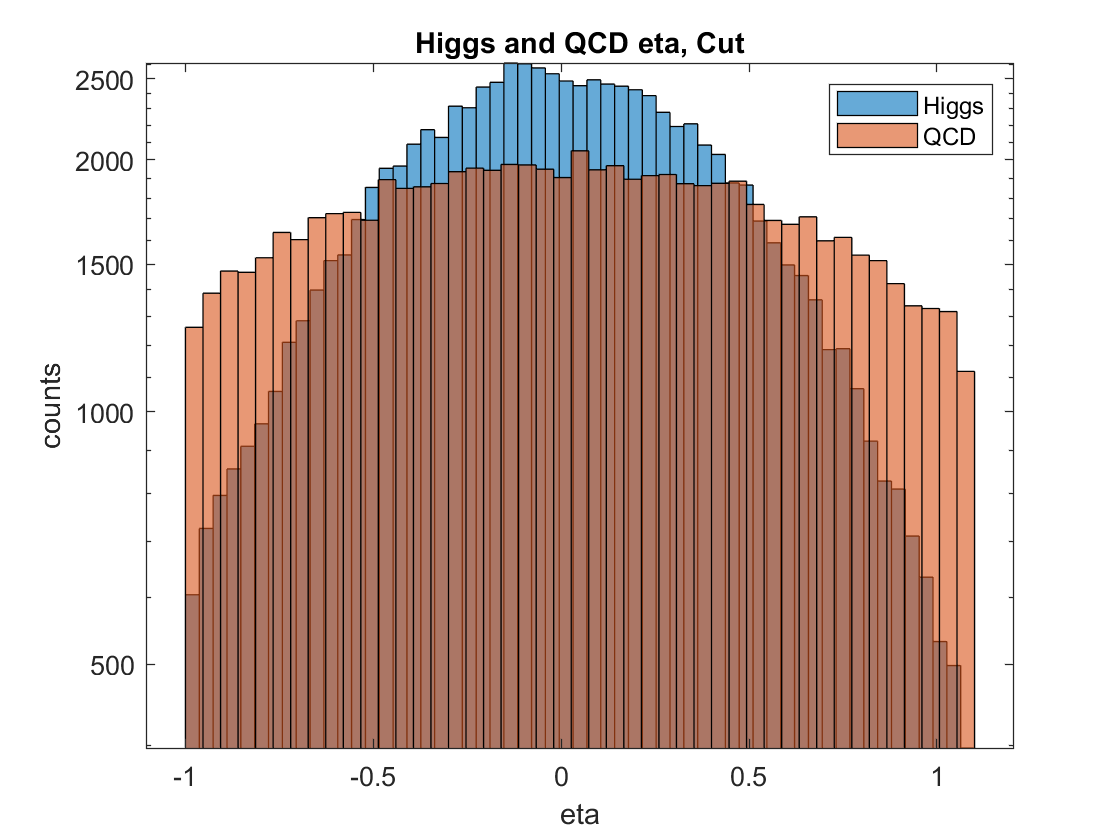

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD eta, Cut')
xlabel('eta')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%phi
hmax = -1.5;
step = 0.05;
j = -3:step:hmax;
k = hmax+step:step:3;
J = length(j);
K = length(k);
r = 3;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
if a == 0
    a = 1;
end
sigs(b,a)

ans = 1.0922

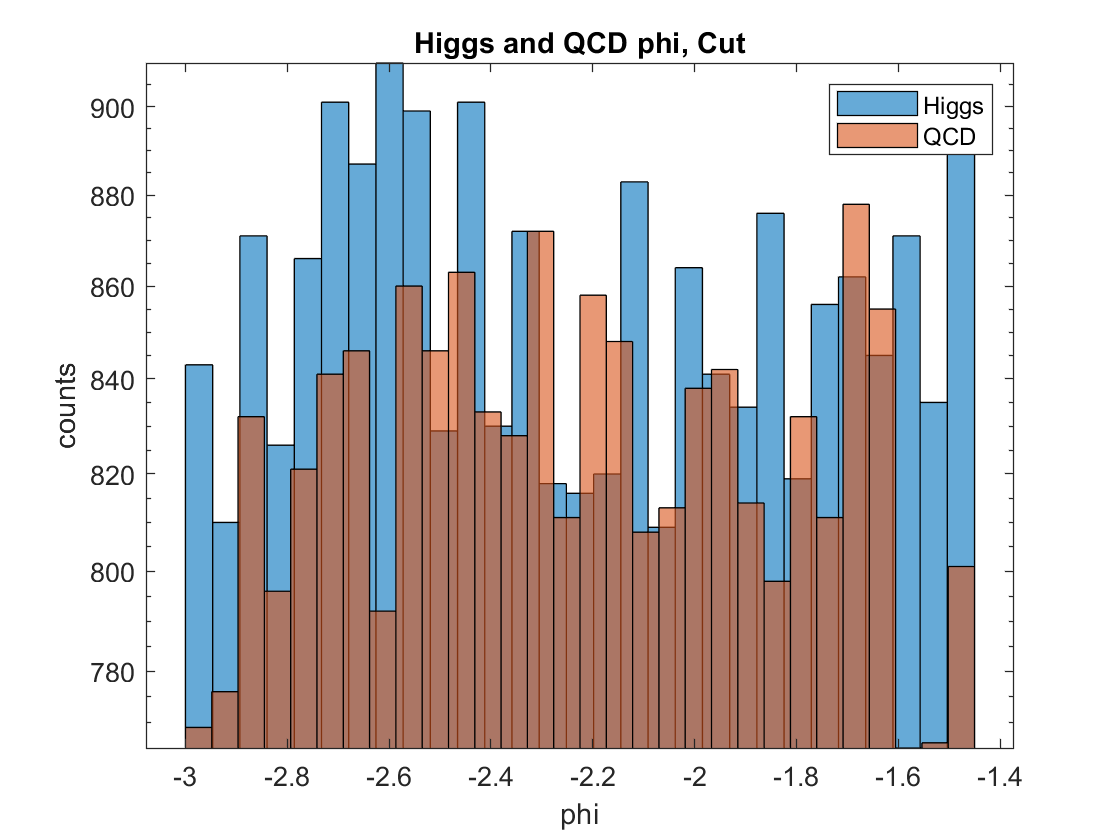

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD phi, Cut')
xlabel('phi')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%ee2
hmax = 0.055;
step = 0.005;
j = 0:step:hmax;
k = hmax+step:step:0.45;
J = length(j);
K = length(k);
r = 5;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 2.1129

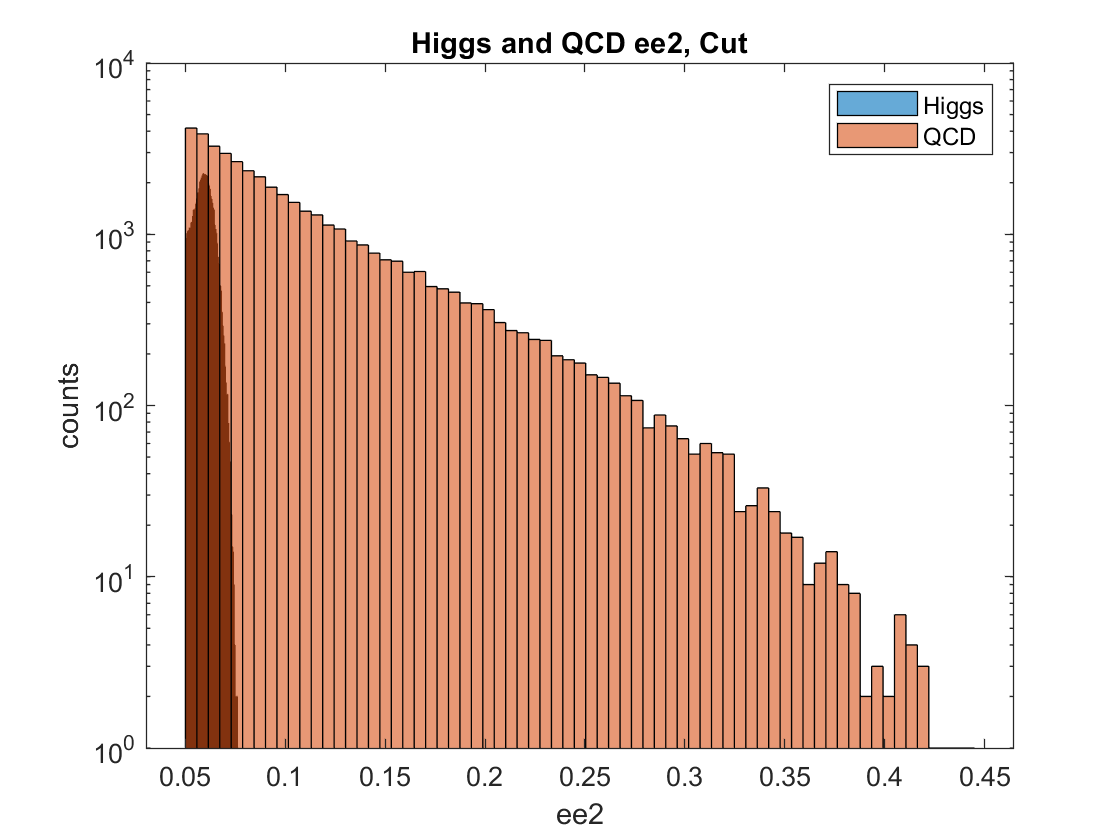

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD ee2, Cut')
xlabel('ee2')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%ee3
hmax = 0;
step = 0.001;
j = 0:step:hmax;
k = hmax+step:step:0.08;
J = length(j);
K = length(k);
r = 6;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.3401

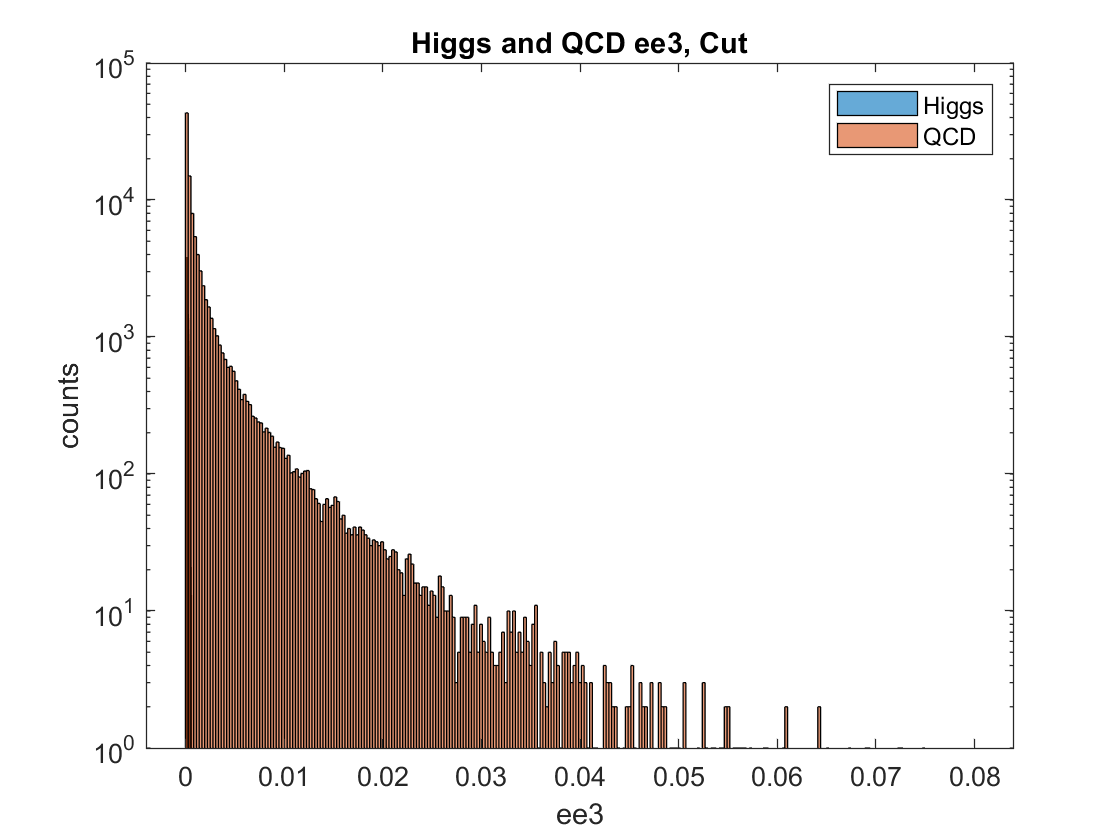

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD ee3, Cut')
xlabel('ee3')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%d2
hmax = 0;
step = 0.5;
j = 0:step:hmax;
k = hmax+step:step:100;
J = length(j);
K = length(k);
r = 7;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 2.0323

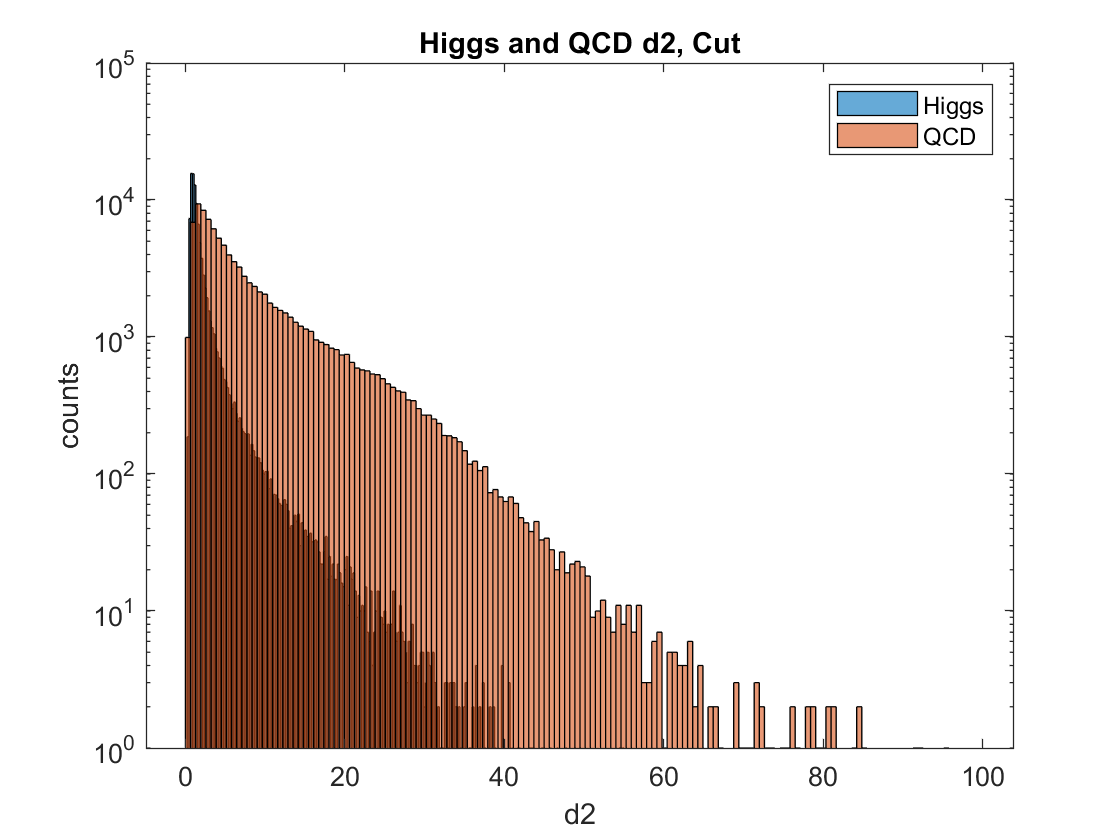

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD d2, Cut')
xlabel('d2')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%angularity
hmax = 0;
step = 0.001;
j = 0:step:hmax;
k = hmax+step:step:0.04;
J = length(j);
K = length(k);
r = 8;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
if a ==0
    a = 1;
end
sigs(b,a)

ans = 1.7652

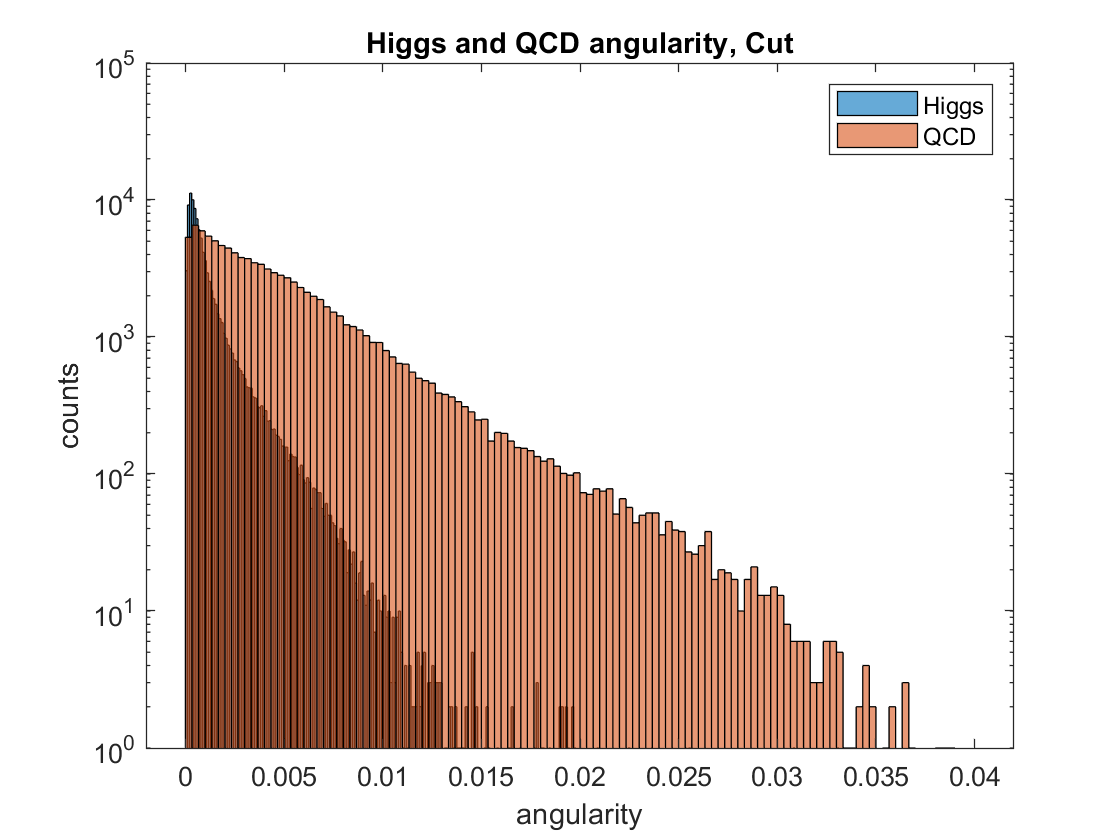

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD angularity, Cut')
xlabel('angularity')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%t1
hmax = 0.6;
step = 0.01;
j = 0.5:step:hmax;
k = hmax+step:step:3;
J = length(j);
K = length(k);
r = 9;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.1197

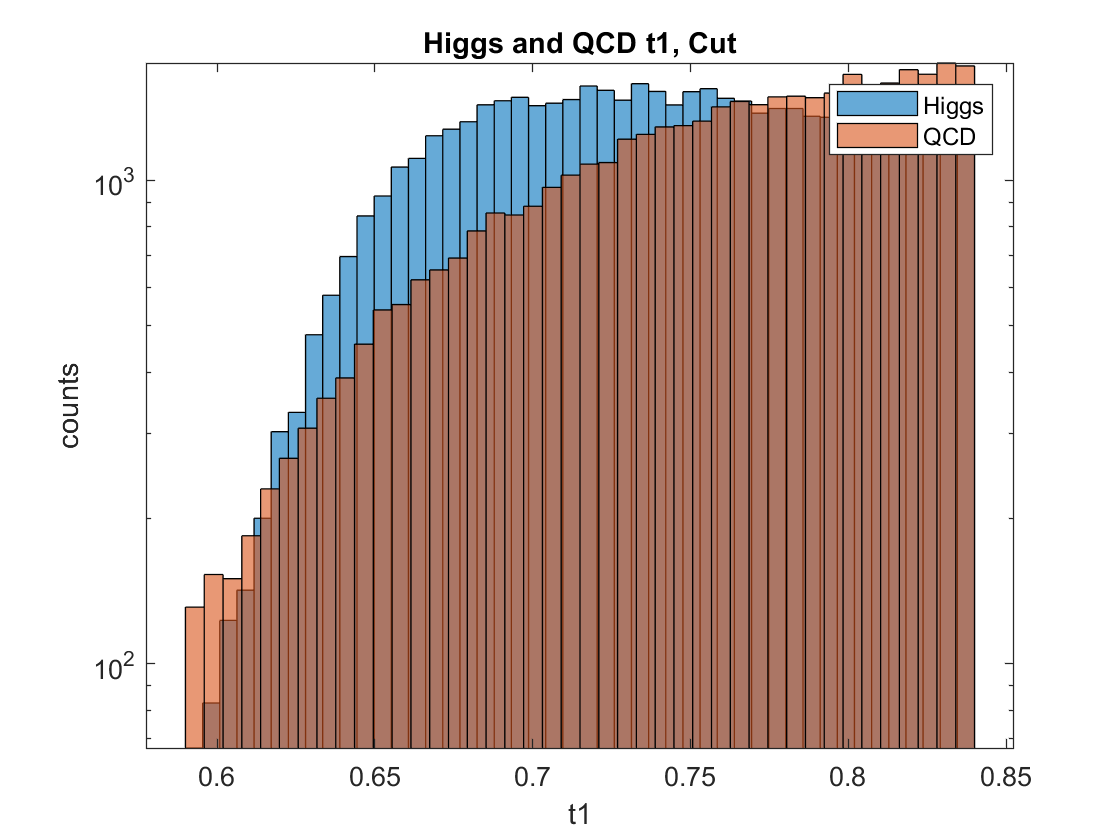

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t1, Cut')
xlabel('t1')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%t2
hmax = 0.19;
step = 0.01;
j = 0:step:hmax;
k = hmax+step:step:1;
J = length(j);
K = length(k);
r = 10;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.8468

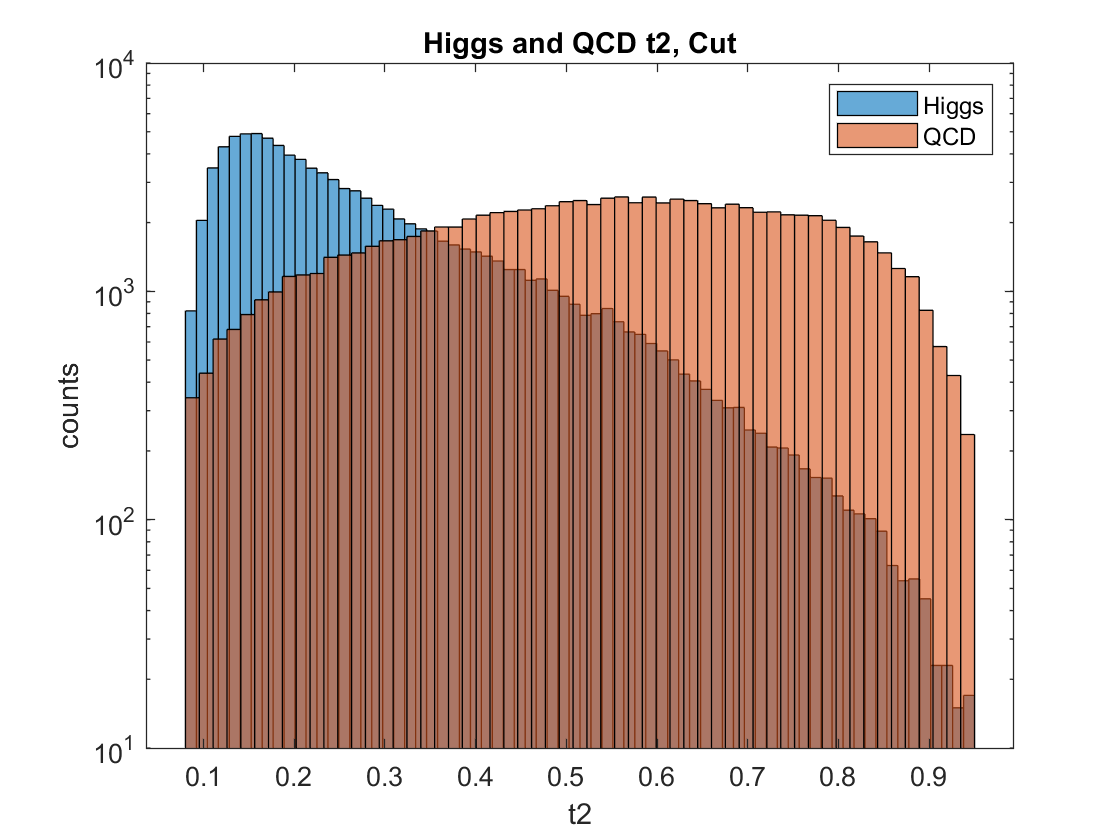

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t2, Cut')
xlabel('t2')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%t3
hmax = 0.18;
step = 0.01;
j = 0:step:hmax;
k = hmax+step:step:1;
J = length(j);
K = length(k);
r = 11;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.8612

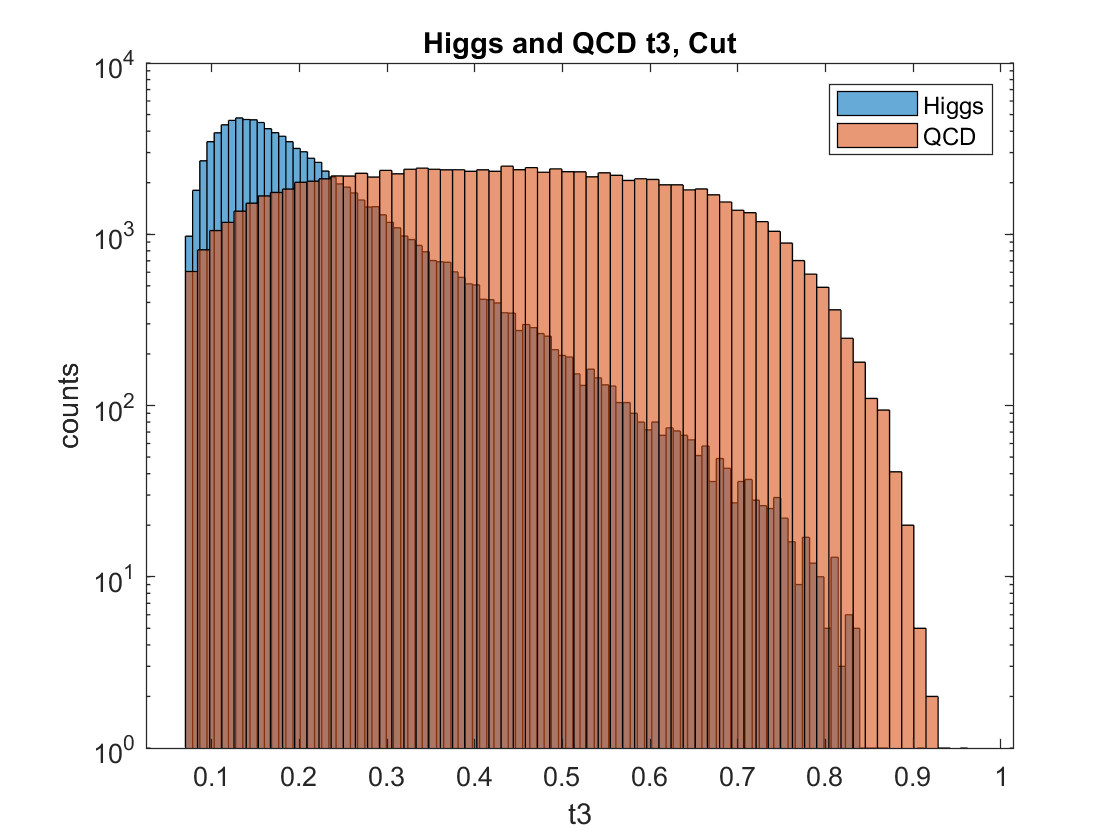

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t3, Cut')
xlabel('t3')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%t21
hmax = 0.2;
step = 0.01;
j = 0:step:hmax;
k = hmax+step:step:1;
J = length(j);
K = length(k);
r = 12;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.8258

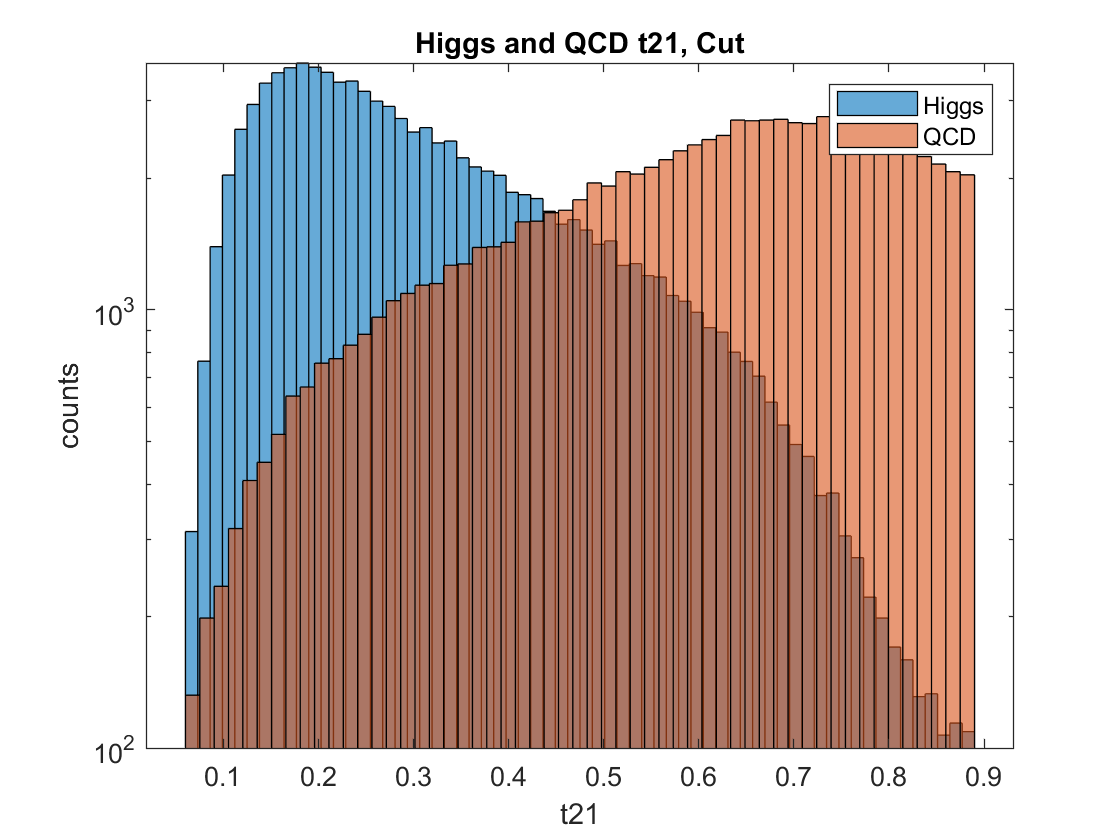

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t21, Cut')
xlabel('t21')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%t32
hmax = 0.45;
step = 0.01;
j = 0:step:hmax;
k = hmax+step:step:1;
J = length(j);
K = length(k);
r = 13;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.1299

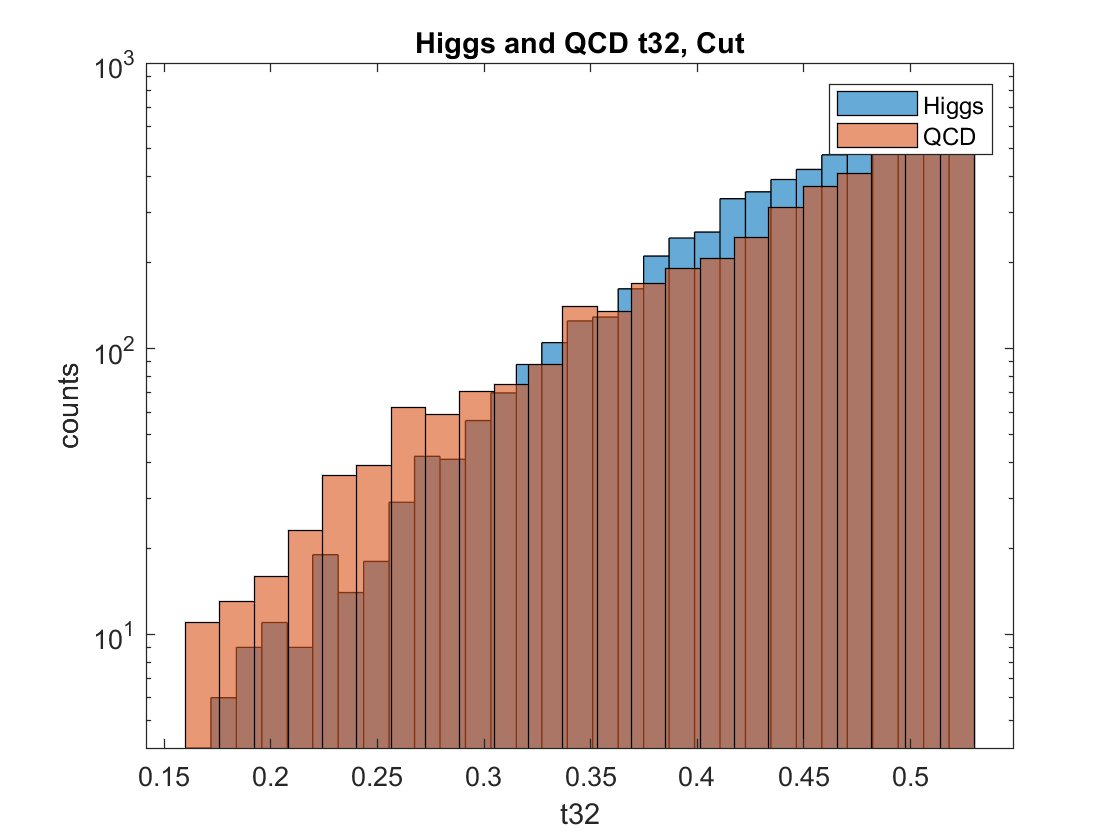

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD t32, Cut')
xlabel('t32')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

%KtDeltaR
hmax = 0.22;
step = 0.01;
j = 0:step:hmax;
k = hmax+step:step:1;
J = length(j);
K = length(k);
r = 14;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 2.0777

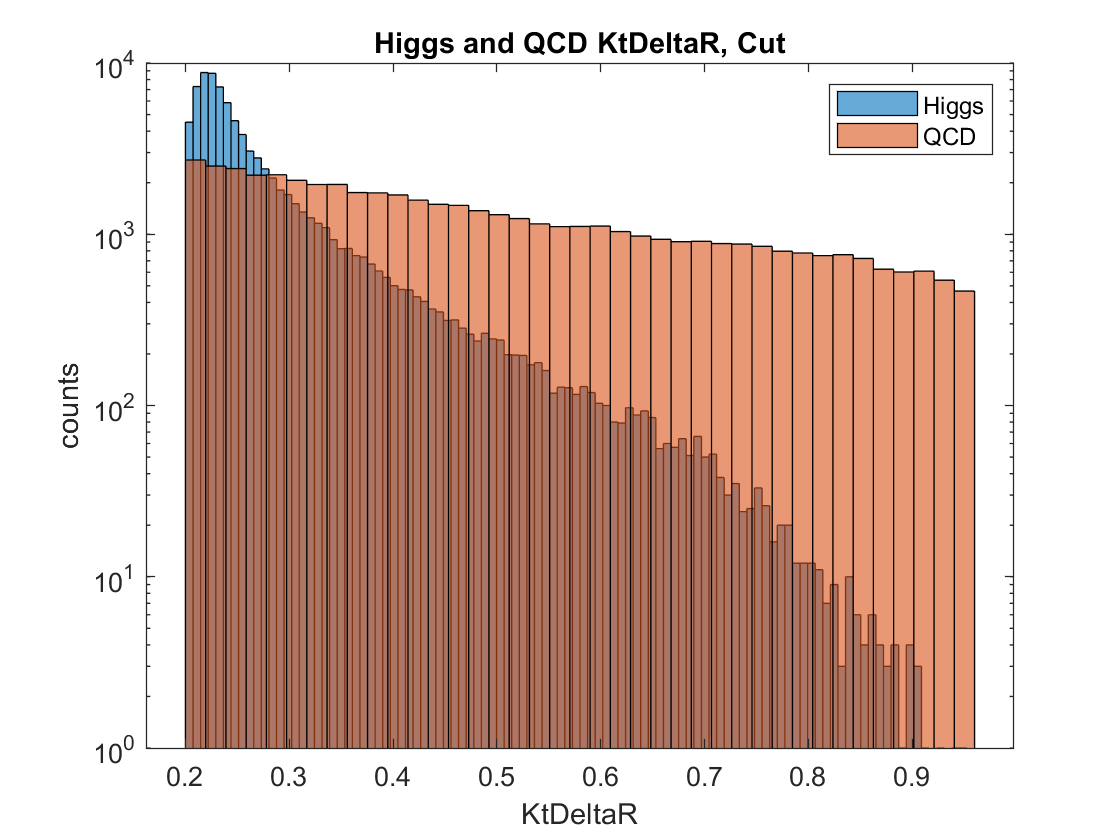

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD KtDeltaR, Cut')
xlabel('KtDeltaR')
ylabel('counts')
legend('Higgs','QCD')
hold off

coordinates(r,1) = j(b);
coordinates(r,2) = k(a);

M

M =     1.1334    1.2092    1.0922    4.4627    2.1129    1.3401    2.0323    1.7652    1.1197    1.8468    1.8612    1.8258    1.1299    2.0777


None of the other features are as discerning as the mass plot, but the feature with the highest significance after mass is ee2, with a maximum significance of about $2\ldotp 11\sigma$. 

Mass and ee2 together could potentially improve significance.

## 4. Multi-Feature Event Selection Optimization

Here I'm using both mass and ee2 to increase significance. I'm doing this by further limiting data selection with limits on mass and ee2 (seen in the 'if' section of the for loop). 

j = 97.5:0.5:125;
k = 125.5:0.2:140.8;
J = length(j);
K = length(k);

q = 0:0.001:0.055;
s = 0.060:0.005:0.44;
Q = length(q);
S = length(s);



sigs = zeros(J,K);
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(4,i)) && (higgs(4,i) < k(K-m)) && (q(n) < higgs(5,i)) && (higgs(5,i) < s(S-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(4,p)) && (qcd(4,p) < k(K-m)) && (q(n) < qcd(5,p)) && (qcd(5,p) < s(S-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear')

A = 16.9927

B = 3695

a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 16.9927

coordinates(15,1) = j(b);
coordinates(15,2) = k(a);
coordinates(16,1) = q(b);
coordinates(16,2) = s(a);

The significance has gone up to $16\ldotp 99\sigma$! Recall significance with no cuts on mass was $1\ldotp 1\sigma$, optimized cuts on mass yielded $4\ldotp 46\sigma$, and optimized cuts on ee2 gave $2\ldotp 11\sigma$. 

Overall, increasing limitations on the datasets greatly improved my estimated significance. 

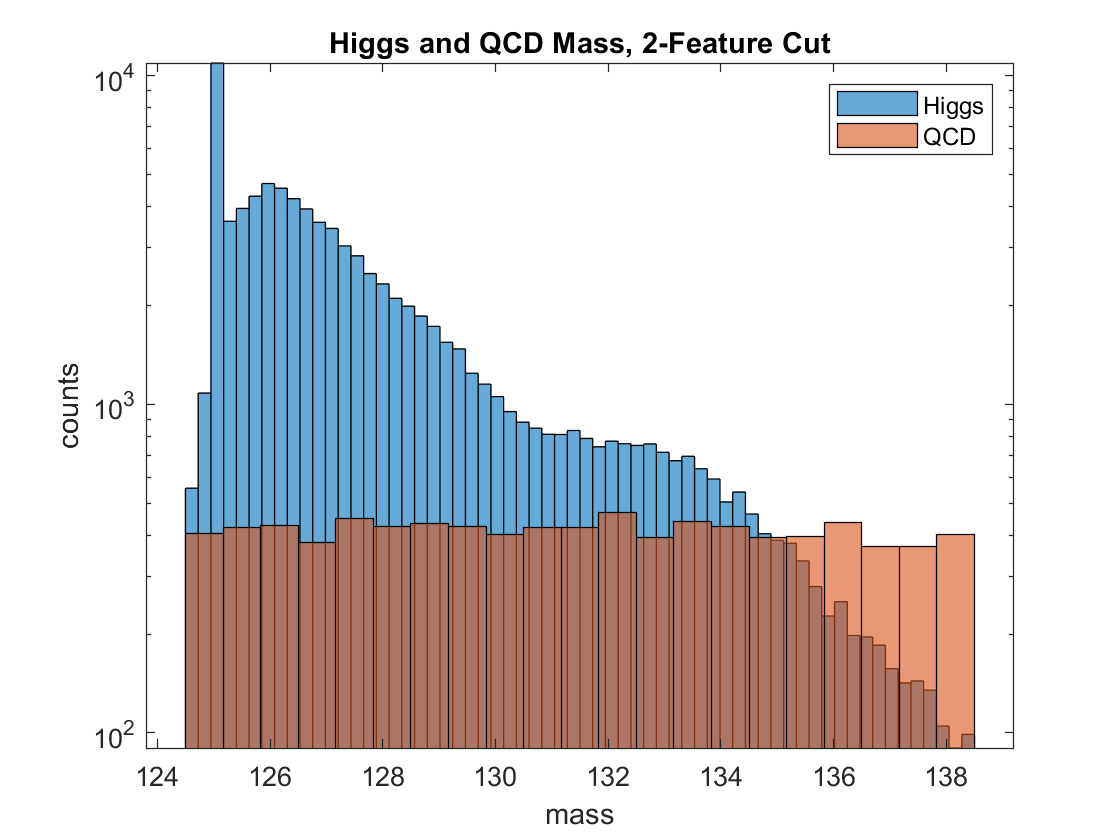

histogram(higgs(4,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
hold on
histogram(qcd(4,:),'BinLimits',[j(b),k(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD Mass, 2-Feature Cut')
xlabel('mass')
ylabel('counts')
legend('Higgs','QCD')
hold off

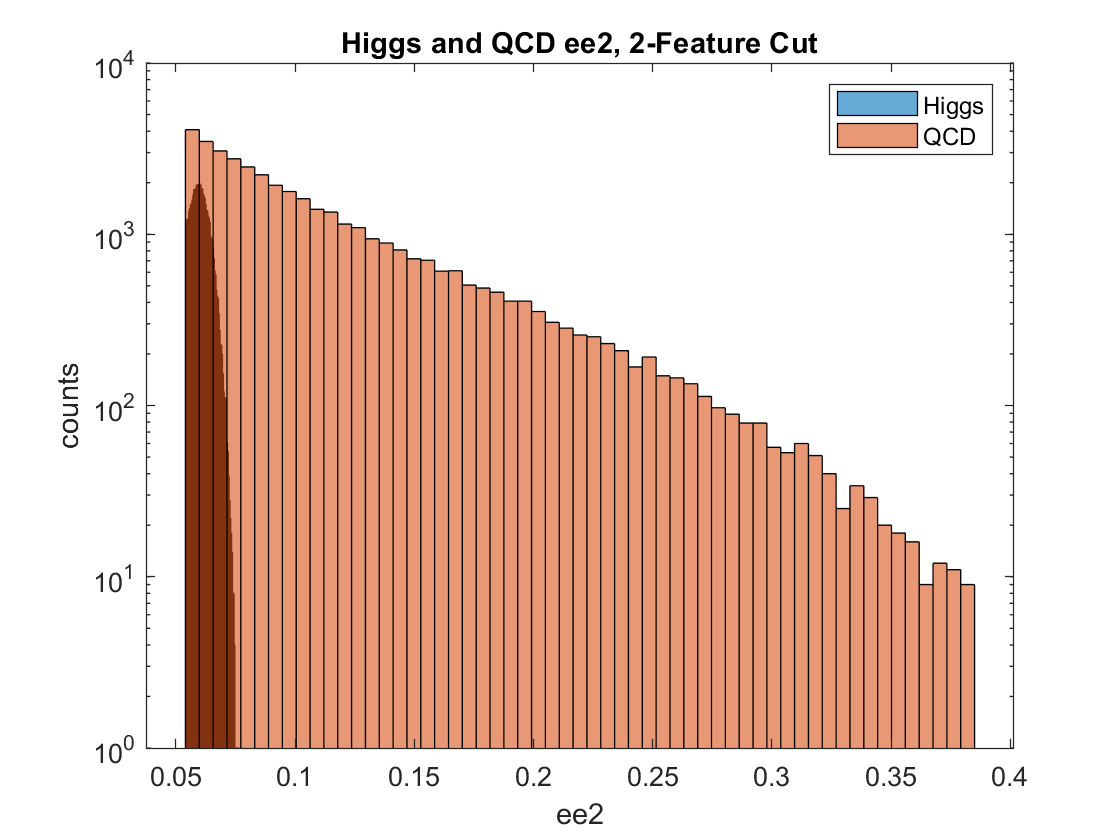

histogram(higgs(5,:),'BinLimits',[q(b),s(a)],'EdgeColor','none');
hold on
histogram(qcd(5,:),'BinLimits',[q(b),s(a)],'EdgeColor','none');
set(gca,'Yscale','log')
title('Higgs and QCD ee2, 2-Feature Cut')
xlabel('ee2')
ylabel('counts')
legend('Higgs','QCD')
hold off

# Lab 8

#### Pseudo-experiment data analysis 

Using your optimized event selection, hunt for your signal by using one of the pseduo-experiment dataset. For each task below, you will choose one of the observed data from your specific pT sample (high pT) to perform the analysis.

Data setup...

h5disp("higgs_100000_pt_1000_1200.h5")
h5disp("qcd_100000_pt_1000_1200.h5")
h5disp("data_lowLumi_pt_1000_1200.h5")
h5disp("data_highLumi_pt_1000_1200.h5")
higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
hlumi = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');
llumi = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_values');

Nhiggs = 50;
Nqcd = 2000;
Ntot = Nhiggs+Nqcd;

## 1. High Luminosity Data

### Plotting observed data, no event selection:

%pt
r = 1;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('pt')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity pt vs. Training Data')
hold off

%eta
r = 2;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('eta')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity eta vs. Training Data')
hold off

%phi
r = 3;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('phi')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity phi vs. Training Data')
hold off

%mass
r = 4;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('mass')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity mass vs. Training Data')
hold off

%ee2
r = 5;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('ee2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity ee2 vs. Training Data')
hold off

%ee3
r = 6;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('ee3')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity ee3 vs. Training Data')
hold off

%d2
r = 7;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('d2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity d2 vs. Training Data')
hold off

%angularity
r = 8;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('angularity')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity angularity vs. Training Data')
hold off

%t1
r = 9;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t1')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t1 vs. Training Data')
hold off

%t2
r = 10;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t2 vs. Training Data')
hold off

%t3
r = 11;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t3')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t3 vs. Training Data')
hold off

%t21
r = 12;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t21')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t21 vs. Training Data')
hold off

%t32
r = 13;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t32')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t32 vs. Training Data')
hold off

%KtDeltaR
r = 14;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('KtDeltaR')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity KtDeltaR vs. Training Data')
hold off

- Plot observed data, overlap with expected signal and background (normalized to observed yields) with optimal event selection.

### Plotting observed data with event selection:

Using coordinates from lab 7.

coordinates;
SIGh = zeros(14,2);

%pt
r = 1;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('pt')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity pt vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%eta
r = 2;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('eta')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity eta vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%phi
r = 3;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('phi')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity phi vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%mass
HL = zeros(1,4066);
r = 4;
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('mass')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity mass vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%ee2
r = 5;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity ee2 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%ee3
r = 6;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee3')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity ee3 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%d2
r = 7;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('d2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity d2 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%angularity
r = 8;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('angularity')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity angularity vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%t1
r = 9;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t1')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t1 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%t2
r = 10;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t2 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%t3
r = 11;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t3')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t3 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%t21
r = 12;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t21')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t21 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%t32
r = 13;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t32')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t32 vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

%KtDeltaR
r = 14;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('KtDeltaR')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity KtDeltaR vs. Training Data, Cut')
hold off

lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr);

SIGh

Sigma values (above) were calculated similarly to the ones in lab 7. Column 1 gives expected sigma values; column 2 gives observed sigma values.

Using mass as an example, the expected significance was $3\ldotp 7\sigma$, and the observed significance was much higher, at $6\ldotp 2\sigma$. This trend did not hold true for all other features. 

## 2. Low Luminosity Data

### Observed data, no event selection:

%pt
r = 1;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('pt')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity pt vs. Training Data')
hold off

%eta
r = 2;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('eta')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity eta vs. Training Data')
hold off

%phi
r = 3;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('phi')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity phi vs. Training Data')
hold off

%mass
r = 4;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('mass')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity mass vs. Training Data')
hold off

%ee2
r = 5;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('ee2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee2 vs. Training Data')
hold off

%ee3
r = 6;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('ee3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee3 vs. Training Data')
hold off

%d2
r = 7;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('d2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity d2 vs. Training Data')
hold off

%angularity
r = 8;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('angularity')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity angularity vs. Training Data')
hold off

%t1
r = 9;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t1')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t1 vs. Training Data')
hold off

%t2
r = 10;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t2 vs. Training Data')
hold off

%t3
r = 11;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t3 vs. Training Data')
hold off

%t21
r = 12;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t21')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t21 vs. Training Data')
hold off

%t32
r = 13;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t32')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t32 vs. Training Data')
hold off

%KtDeltaR
r = 14;
histogram(llumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('KtDeltaR')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity KtDeltaR vs. Training Data')
hold off

### Observed data with event selection:

coordinates;
SIGl = zeros(14,2);

%pt
r = 1;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('pt')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity pt vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%eta
r = 2;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('eta')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity eta vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%phi
r = 3;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('phi')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity phi vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%mass
LL = zeros(1,442);
r = 4;
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('mass')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity mass vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%ee2
r = 5;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee2 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%ee3
r = 6;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee3 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%d2
r = 7;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('d2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity d2 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%angularity
r = 8;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('angularity')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity angularity vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%t1
r = 9;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t1')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t1 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%t2
r = 10;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t2 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%t3
r = 11;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t3 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%t21
r = 12;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t21')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t21 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%t32
r = 13;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t32')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t32 vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

%KtDeltaR
r = 14;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('KtDeltaR')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity KtDeltaR vs. Training Data, Cut')
hold off

lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

r = 4;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = 1;
    else
        LL(i) = 0;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = 1;
    else
        QCD(j) = 0;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = 1;
    else
        HIG(j) = 0;
    end   
end

lll = length(llumi(r,:));
lllc = sum(LL);
lqcd = length(qcd(r,:));
lqcdc = sum(QCD);
lhig = length(higgs(r,:));
lhigc = sum(HIG);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = abs(norminv(pr));

SIGl

Once again using mass as the example, significance went down ($3\ldotp 7\sigma$ to $2\sigma$), which overall was a trend in the low luminosity dataset with a few counterexamples (ex. pt).

## 3. 95% Confidence Level of Signal Yields

- In the low luminosity data, the observed significance is less than 5σσ. We will calculate the 95% confidence level upper limit of signal yield.

- Evaluate the expected 95% confidence level upper limit

- Evaluate the observed 95% confidence level upper limit

- Compare expectation to observation. Comment on your finding.

- (nope for at least the time being)

toc